% PROBLEM 1

close all
clear
clc

% Define the system parameters
m1 = 20; % kg
m2 = 40; % kg
m3 = 30; % kg
k1 = 2000; % N/m
k2 = 4000; % N/m

% Define the system matrices
Ap = [0 0 0 1 0 0;
      0 0 0 0 1 0;
      0 0 0 0 0 1;
      -k1/m1 k1/m1 0 0 0 0;
      k1/m2 (-k1-k2)/m2 k2/m2 0 0 0;
      0 k2/m3 -k2/m3 0 0 0]

Ap =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
 -100.0000  100.0000         0         0         0         0
   50.0000 -150.0000  100.0000         0         0         0
         0  133.3333 -133.3333         0         0         0


Bp = [0; 0; 0; 1/m1; 0; 0]

Bp =          0
         0
         0
    0.0500
         0
         0


Dp = [0; 0; 0; 1/m1; 0; 0]

Dp =          0
         0
         0
    0.0500
         0
         0


Cp2 = [0 0 1 0 0 0]

Cp2 =      0     0     1     0     0     0


By2 = 0

By2 = 0

Dy = 0

Dy = 0

% Lumped system representation
A = Ap;
B = [Dp Bp];
C = [zeros(size(Cp2)); Cp2];
D = [Dy zeros(size(By2)); zeros(size(Dy)) By2];
S = ltisys(A, B, C, D)

S =          0         0         0    1.0000         0         0         0         0    6.0000
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
 -100.0000  100.0000         0         0         0         0    0.0500    0.0500         0
   50.0000 -150.0000  100.0000         0         0         0         0         0         0
         0  133.3333 -133.3333         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      -Inf



% State-feedback controller G1 to minimize the energy-to-peak gain Γep
r = size(By2);
obj = [0 0 0 1]; % Optimal H2 control design objective
region = lmireg; % h (half-plane) --> l (LHP, i.e., Re(z) < x0) --> -1 (x0 = -1)



Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


[g1opt, g2opt, G1, Scl, X] = msfsyn(S, r, obj, region)


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8                   0.123781
     9                   0.101980
    10                   0.101980
    11                   0.028857
    12                   0.028857
    13                   0.028857
    14                   0.012000
    15                   0.012000
    16                   0.010372
    17                   0.010372
    18                   0.010372
    19               6.093835e-03
    20               6.093835e-03
    21               6.093835e-03
    22               3.043563e-03
    23               3.043563e-03
    24               3.043563e-03
    25               1.240950e-03
    26               1.240950e-03
    27               1.231455e-03
    28               3.550594e-04
    29               2.

g2opt = 9.5736e-04

G1 = 1.0e+11 *

   -0.0008   -0.2312   -1.9312   -0.0000   -0.0024   -0.0996


Scl = 1.0e+09 *

         0         0         0    0.0000         0         0         0    0.0000
         0         0         0         0    0.0000         0         0         0
         0         0         0         0         0    0.0000         0         0
   -0.0038   -1.1562   -9.6558   -0.0000   -0.0120   -0.4980    0.0000         0
    0.0000   -0.0000    0.0000         0         0         0         0         0
         0    0.0000   -0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0      -Inf


X = 1.0e+06 *

    0.0003    0.0000   -0.0000   -0.0080   -0.0002   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0080    0.0000   -0.0000    1.3121   -0.0003   -0.0000
   -0.0002   -0.0000    0.0000   -0.0003    0.0002    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000



% Closed-loop system
Acl = Ap + Bp*G1

Acl = 1.0e+09 *

         0         0         0    0.0000         0         0
         0         0         0         0    0.0000         0
         0         0         0         0         0    0.0000
   -0.0038   -1.1562   -9.6558   -0.0000   -0.0120   -0.4980
    0.0000   -0.0000    0.0000         0         0         0
         0    0.0000   -0.0000         0         0         0


h2_norm = norm2(Scl)

h2_norm = 1.8822e-11

% Scl = ss(Acl, [Dp zeros(size(Bp))], C, D)
% h2_norm = norm(Scl, 2)

% Verification
if((h2_norm < g2opt) && all(real(eig(Acl)) < -1.0))
    disp('Verification of H2 norm and pole location constraints successful!')
else
    disp('Verification of H2 norm and pole location constraints failed!')
end

Verification of H2 norm and pole location constraints successful!


% Define the lumped (disturbance + control) input
t = 0:0.01:10;
w_amplitude = 100.0;
w_duration = 2;
w_pulse = w_amplitude * (t >= 0 & t <= w_duration);
u = zeros(size(w_pulse));
w = [w_pulse; u];

% Simulate the open-loop system response
Sol = ss(A, B, C, D)

Sol =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       0       0       1       0       0
   x2       0       0       0       0       1       0
   x3       0       0       0       0       0       1
   x4    -100     100       0       0       0       0
   x5      50    -150     100       0       0       0
   x6       0   133.3  -133.3       0       0       0
 
  B = 
         u1    u2
   x1     0     0
   x2     0     0
   x3     0     0
   x4  0.05  0.05
   x5     0     0
   x6     0     0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   0   0
   y2   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


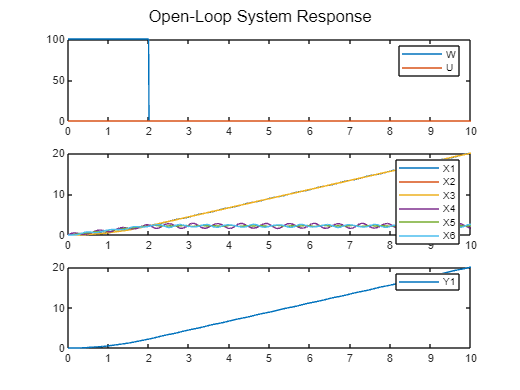

[y_ol, t_out, x_ol] = lsim(Sol, w', t);

% Plot the results
figure;
sgtitle('Open-Loop System Response');
subplot(3, 1, 1);
plot(t, w(1, :), t, w(2, :));
legend('W', 'U');
subplot(3, 1, 2);
plot(t, x_ol(:, 1), ...
     t, x_ol(:, 2), ...
     t, x_ol(:, 3), ...
     t, x_ol(:, 4), ...
     t, x_ol(:, 5), ...
     t, x_ol(:, 6) ...
     );
legend('X1', 'X2', 'X3', 'X4', 'X5', 'X6');
subplot(3, 1, 3);
plot(t, y_ol(:, 2));
legend('Y1');


% Simulate the closed-loop system response
Scl = ss(Acl, [Dp zeros(size(Bp))], C, D)

Scl =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           0           0           1           0           0
   x2           0           0           0           0           1           0
   x3           0           0           0           0           0           1
   x4  -3.805e+06  -1.156e+09  -9.656e+09   -1.15e+04  -1.205e+07   -4.98e+08
   x5          50        -150         100           0           0           0
   x6           0       133.3      -133.3           0           0           0
 
  B = 
         u1    u2
   x1     0     0
   x2     0     0
   x3     0     0
   x4  0.05     0
   x5     0     0
   x6     0     0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   0   0
   y2   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


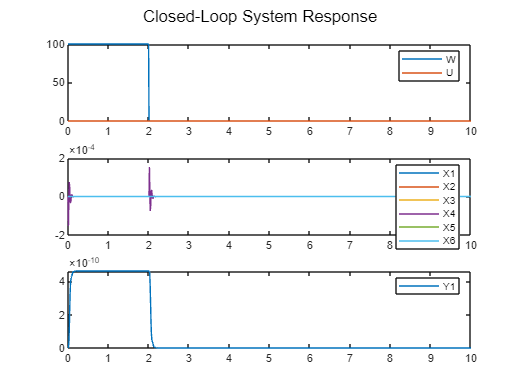

[y_cl, t_out, x_cl] = lsim(Scl, w', t);

% Plot the results
figure;
sgtitle('Closed-Loop System Response');
subplot(3, 1, 1);
plot(t, w(1, :), t, w(2, :));
legend('W', 'U');
subplot(3, 1, 2);
plot(t, x_cl(:, 1), ...
     t, x_cl(:, 2), ...
     t, x_cl(:, 3), ...
     t, x_cl(:, 4), ...
     t, x_cl(:, 5), ...
     t, x_cl(:, 6) ...
     );
legend('X1', 'X2', 'X3', 'X4', 'X5', 'X6');
subplot(3, 1, 3);
plot(t, y_cl(:, 2));
legend('Y1');

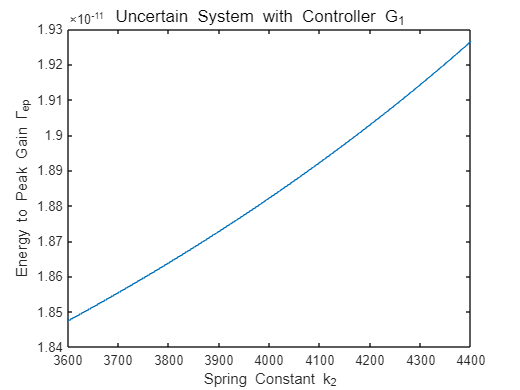

% Define uncertain system parameters
m1 = 20; % kg
m2 = 40; % kg
m3 = 30; % kg
k1 = 2000; % N/m
i = 1;
for k2 = 3600:1:4400 % N/m
    % Define the system matrices
    Ap = [0 0 0 1 0 0;
          0 0 0 0 1 0;
          0 0 0 0 0 1;
          -k1/m1 k1/m1 0 0 0 0;
          k1/m2 (-k1-k2)/m2 k2/m2 0 0 0;
          0 k2/m3 -k2/m3 0 0 0];
    Bp = [0; 0; 0; 1/m1; 0; 0];
    Dp = [0; 0; 0; 1/m1; 0; 0];
    Cp2 = [0 0 1 0 0 0];
    By2 = 0;
    Dy = 0;
    % Lumped system representation
    A = Ap;
    B = [Dp Bp];
    C = [zeros(size(Cp2)); Cp2];
    D = [Dy zeros(size(By2)); zeros(size(Dy)) By2];
    % Closed-loop system
    Acl = Ap + Bp*G1;
    Scl = ltisys(Acl, [Dp zeros(size(Bp))], C, D);
    h2_norm(i) = norm2(Scl);
    % Scl = ss(Acl, [Dp zeros(size(Bp))], C, D);
    % h2_norm(i) = norm(Scl, 2);
    i = i+1;
end

figure;
sgtitle('Uncertain System with Controller G_1');
plot(3600:1:4400, h2_norm)
xlabel('Spring Constant k_2')
ylabel('Energy to Peak Gain Γ_ep')

% Define the system parameters
m1 = 20; % kg
m2 = 40; % kg
m3 = 30; % kg
k1 = 2000; % N/m

% System matrices in affine form
A0 = [0 0 0 1 0 0;
      0 0 0 0 1 0;
      0 0 0 0 0 1;
      -k1/m1 k1/m1 0 0 0 0;
      k1/m2 -k1/m2 0 0 0 0;
      0 0 0 0 0 0]

A0 =      0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
  -100   100     0     0     0     0
    50   -50     0     0     0     0
     0     0     0     0     0     0


A1 = [0 0 0 0 0 0;
      0 0 0 0 0 0;
      0 0 0 0 0 0;
      0 0 0 0 0 0;
      0 -1/m2 1/m2 0 0 0;
      0 1/m3 -1/m3 0 0 0]

A1 =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0   -0.0250    0.0250         0         0         0
         0    0.0333   -0.0333         0         0         0


B0 = B

B0 =          0         0
         0         0
         0         0
    0.0500    0.0500
         0         0
         0         0


C0 = C

C0 =      0     0     0     0     0     0
     0     0     1     0     0     0


D0 = D

D0 =      0     0
     0     0



% Uncertain LTI system in affine form
S0 = ltisys(A0, B0, C0, D0, 1)

S0 =          0         0         0    1.0000         0         0         0         0    6.0000
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
 -100.0000  100.0000         0         0         0         0    0.0500    0.0500         0
   50.0000  -50.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      -Inf


S1 = ltisys(A1, zeros(size(B0)), zeros(size(C0)), zeros(size(D0)), 0)

S1 =    0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   6.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0250 + 0.0000i   0.0250 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0333 + 0.0000i  -0.0333 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i  


% Parameter vector
P = pvec('box', [3600, 4400]) % k2

P =            1        3600        4400           0           0
           1           0           0           0           0



% Affine system
affsys = psys(P, [S0, S1])

affsys = 1.0e+03 *

     -Inf + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0060 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0010i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0060 + 0.0000i   0.0010 + 0.0000i   3.6000 + 0.0000i   4.4000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0020 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0010i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 


% State-feedback controller G2 to minimize the energy-to-peak gain Γep
r = size(By2);
obj = [0 0 0 1]; % Optimal H2 control design objective
region = lmireg; % h (half-plane) --> l (LHP, i.e., Re(z) < x0) --> -1 (x0 = -1)



Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


[g1opt, g2opt, G2, Scl, X] = msfsyn(affsys, r, obj, region)


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11                   0.174617
    12                   0.084142
    13                   0.084142
    14                   0.084142
    15                   0.035606
    16                   0.035606
    17                   0.035606
    18                   0.019613
    19                   0.019613
    20                   0.019613
    21                   0.011597
    22                   0.011597
    23                   0.011597
    24               7.440620e-03
    25               7.440620e-03
    26               7.440620e-03
    27               4.761071e-03
    28               4.761071e-03
    29               4.761071e-03
    30               3.057379e-03
    31               3.057379e-03
  

g2opt = 9.8038e-04

G2 = 1.0e+11 *

   -0.0009   -0.2480   -1.9988   -0.0000   -0.0028   -0.0997


Scl = 1.0e+09 *

      -Inf         0         0         0         0    0.0000         0         0         0    0.0000         0         0         0         0    0.0000         0         0         0    0.0000
    0.0000         0         0         0         0         0    0.0000         0         0         0         0         0         0         0         0    0.0000         0         0         0
    0.0000         0         0         0         0         0         0    0.0000         0         0         0         0         0         0         0         0    0.0000         0         0
    0.0000         0   -0.0046   -1.2400   -9.9938   -0.0000   -0.0138   -0.4987    0.0000         0         0   -0.0046   -1.2400   -9.9938   -0.0000   -0.0138   -0.4987    0.0000         0
    0.0000         0    0.0000   -0.0000    0.0000         0         0         0         0         0         0    0.0000   -0.0000    0.0000         0         0         0         0         0
    0.0000         0        

X = 1.0e+05 *

    0.0013    0.0000    0.0000   -0.0411   -0.0008   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0411    0.0000   -0.0000    5.9055    0.0058    0.0001
   -0.0008   -0.0000    0.0000    0.0058    0.0007    0.0000
   -0.0000   -0.0000   -0.0000    0.0001    0.0000    0.0000



disp('Optimal guaranteed energy-to-peak gain for the uncertain system is:')

Optimal guaranteed energy-to-peak gain for the uncertain system is:


disp(g2opt)

   9.8038e-04



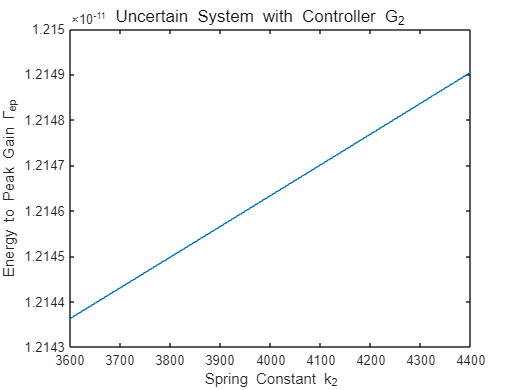

% Define uncertain system parameters
m1 = 20; % kg
m2 = 40; % kg
m3 = 30; % kg
k1 = 2000; % N/m
i = 1;
for k2 = 3600:1:4400 % N/m
    % Define the system matrices
    Ap = [0 0 0 1 0 0;
          0 0 0 0 1 0;
          0 0 0 0 0 1;
          -k1/m1 k1/m1 0 0 0 0;
          k1/m2 (-k1-k2)/m2 k2/m2 0 0 0;
          0 k2/m3 -k2/m3 0 0 0];
    Bp = [0; 0; 0; 1/m1; 0; 0];
    Dp = [0; 0; 0; 1/m1; 0; 0];
    Cp2 = [0 0 1 0 0 0];
    By2 = 0;
    Dy = 0;
    % Lumped system representation
    A = Ap;
    B = [Dp Bp];
    C = [zeros(size(Cp2)); Cp2];
    D = [Dy zeros(size(By2)); zeros(size(Dy)) By2];
    % Closed-loop system
    Acl = Ap + Bp*G2;
    Scl = ltisys(Acl, [Dp zeros(size(Bp))], C, D);
    h2_norm(i) = norm2(Scl);
    % Scl = ss(Acl, [Dp zeros(size(Bp))], C, D);
    % h2_norm(i) = norm(Scl, 2);
    i = i+1;
end

figure;
sgtitle('Uncertain System with Controller G_2');
plot(3600:1:4400, h2_norm)
xlabel('Spring Constant k_2')
ylabel('Energy to Peak Gain Γ_ep')